
cd('/Volumes/PcSSDA/AChMut/20220714_PM29_111_AChmut_RvR_002')
ExperimentName='20220714_PM29_111_AChmut_RvR_002'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;
mouse='111'

mouse = '111'


analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

i=1;
filename=[analysis_name,num2str(i),'_20220802.mat'];
load(filename)

speed_csv=['speed/',ExperimentName,'_speed0.csv'];
[time_of_speed speed]=csvimport(speed_csv,'columns',[1,2],'noHeader',true);
time_of_speed(1)=[];
speed(1)=[];

speed=str2double(speed); 

time_of_speed_seconds=[];
time_of_speed_string=string;
reference_time=[time_of_speed{1}(1:10),' ',time_of_speed{1}(12:27)]

reference_time = '2022-07-14 16:01:04.9521152'

reference_time=datetime(reference_time)

reference_time = datetime
   14-Jul-2022 16:01:04



for i=1:size(time_of_speed,1)
    hour_num=str2num(time_of_speed{i}(12:13));
    min_num=str2num(time_of_speed{i}(15:16));
    sec_num=str2num(time_of_speed{i}(18:27));
    time_of_speed_seconds(i)=3600*hour_num+60*min_num+sec_num;
%     a=[time_of_speed{i}(1:10),' ',time_of_speed{i}(12:27)];
%     time_of_speed_string(i)=a;
%     time_of_speed_seconds(i)=second(datetime(a)-reference_time);
end


time_of_speed_seconds=time_of_speed_seconds-time_of_speed_seconds(1);

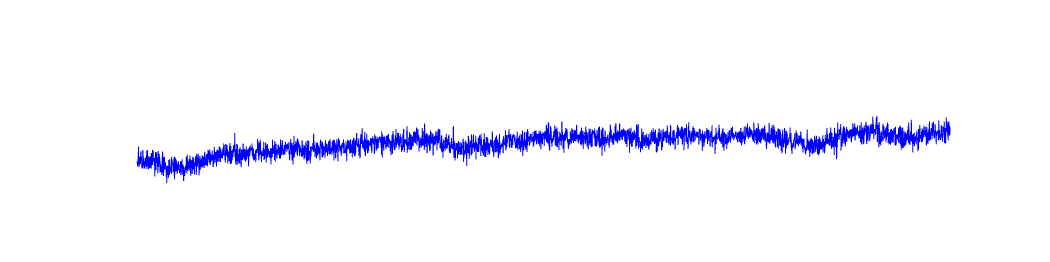

figure1=figure;
figure1.Position=[10 10 1200 300];
ax=gca;
ax.FontSize=20;
% yyaxis left
plot(time,tau_empTrunc,'Color','b');
% ylabel('Lifetime (ns)','FontSize',24)
ylim([4.15 4.3])
xlim([0 3600])
axis off
% ax.XAxis.Visible = 'off';
box off

% yticks([4.15 4.20 4.25 4.3])

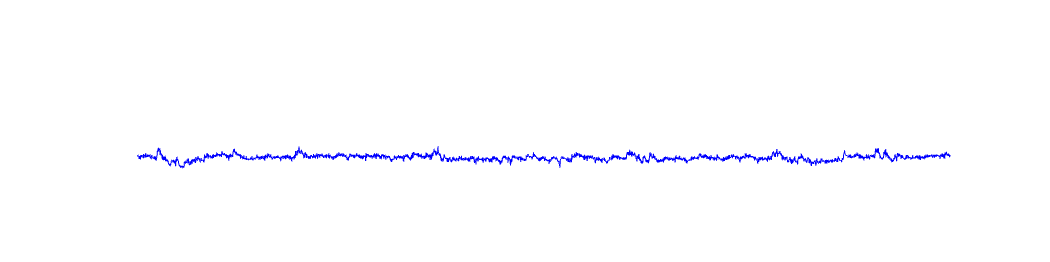

figure3=figure;
figure3.Position=[10 10 1200 300];
ax=gca;
ax.FontSize=20;
% yyaxis left
plot(time,photoncount,'Color','b');
% ylabel('Lifetime (ns)','FontSize',24)
ylim([350000 500000])
xlim([0 3600])
axis off
% ax.XAxis.Visible = 'off';
box off

% yticks([4.15 4.20 4.25 4.3])

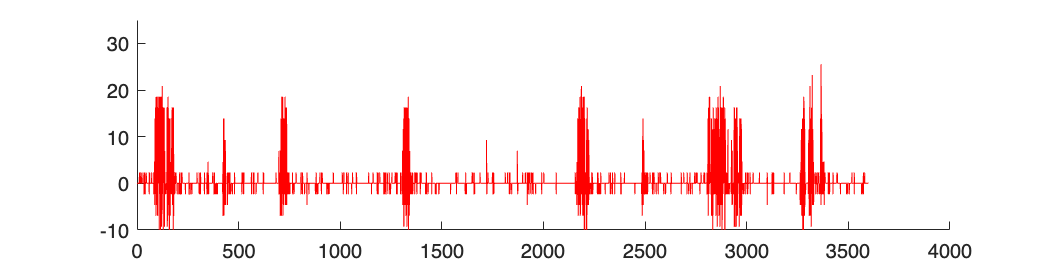


figure2=figure;
figure2.Position=[10 10 1200 300];
% yyaxis right
plot(time_of_speed_seconds,speed, 'Color','r')
% ylabel('Speed cm/s','FontSize',24)
ylim([-10 35])
% yticks([-10 0 10 20])
% xlim([400 1500])
% xticks([0 100 200 300])
% xlabel('Time (sec)','FontSize',24)
% legend('Lifetime','Speed','FontSize',20)
box off

% axis off

max(photoncount) - min(photoncount)

ans = 15709

max(speed) - min(speed)

ans = 41.7481

max(tau_empTrunc) - min(tau_empTrunc)

ans = 0.0478

figure1=figure;
figure1.Position=[10 10 1200 300];
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


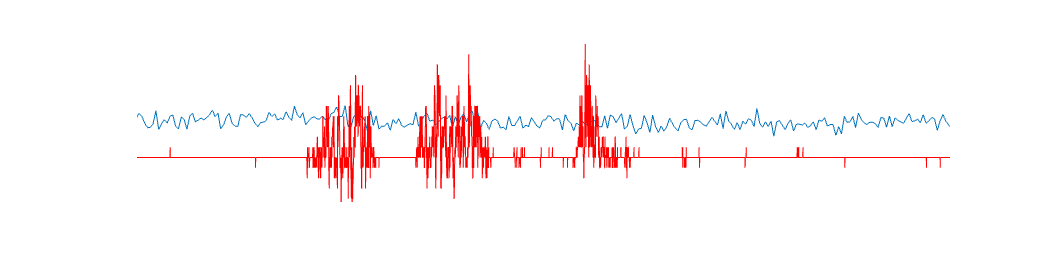

yyaxis left
plot(time,tau_empTrunc);
xlim([3200 3500])
ylim([4.15 4.3])
set(gca, 'XColor','none')
set(gca, 'YColor','none')
yyaxis right
plot(time_of_speed_seconds,speed, 'Color','r')
% ylabel('Speed cm/s','FontSize',24)
ylim([-10 30])
ylabel('Speed (cm/s)')
% yticks([-10 0 10 20])
xlim([3200 3500])
set(gca,'ytick',[0 20])
axis off
box off

% title('Lifetime')

figure1=figure;
figure1.Position=[10 10 1200 300];
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


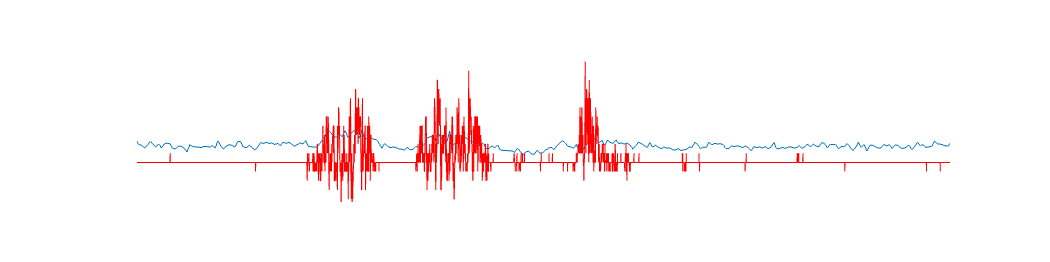

yyaxis left
plot(time,photoncount);
xlim([3200 3500])
ylim([380000 450000])
set(gca, 'XColor','none')
set(gca, 'YColor','none')
yyaxis right
plot(time_of_speed_seconds,speed, 'Color','r')
% ylabel('Speed cm/s','FontSize',24)
ylim([-10 35])
% yticks([-10 0 10 20])
xlim([3200 3500])
set(gca,'ytick',[0 20])
ylabel('Speed (cm/s)')
axis off
box off

% title('Intensity')

cd('/Volumes/PcSSDA/RvR/20220328_1630_RvR_001')
ExperimentName='20220328_1630_RvR_001'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;
mouse='1630';
Recording='1';

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 
i=1;
filename=[analysis_name,num2str(i),'_20220512.mat'];
load(filename)

speed_csv=['data/',ExperimentName,'_speed0.csv'];
[time_of_speed speed]=csvimport(speed_csv,'columns',[1,2],'noHeader',true);
time_of_speed(1)=[];
speed(1)=[];

speed=str2double(speed); 

time_of_speed_seconds=[];
time_of_speed_string=string;
reference_time=[time_of_speed{1}(1:10),' ',time_of_speed{1}(12:27)]

reference_time = '2022-03-28 13:11:17.5804416'

reference_time=datetime(reference_time)

reference_time = datetime
   28-Mar-2022 13:11:17



for i=1:size(time_of_speed,1)
    hour_num=str2num(time_of_speed{i}(12:13));
    min_num=str2num(time_of_speed{i}(15:16));
    sec_num=str2num(time_of_speed{i}(18:27));
    time_of_speed_seconds(i)=3600*hour_num+60*min_num+sec_num;
%     a=[time_of_speed{i}(1:10),' ',time_of_speed{i}(12:27)];
%     time_of_speed_string(i)=a;
%     time_of_speed_seconds(i)=second(datetime(a)-reference_time);
end


time_of_speed_seconds=time_of_speed_seconds-time_of_speed_seconds(1);

figure1=figure;
figure1.Position=[10 10 1200 300];
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


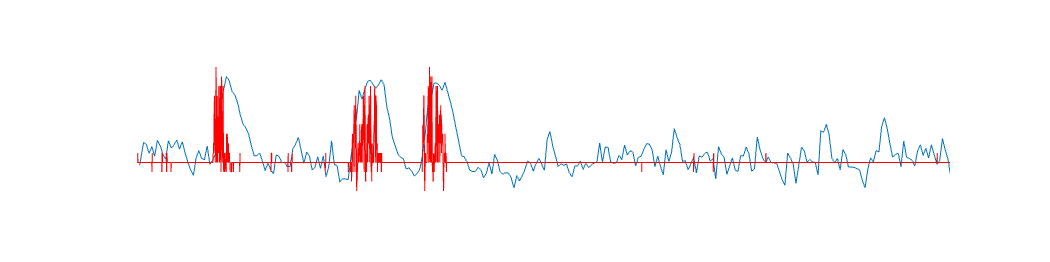

yyaxis left
plot(time,tau_empTrunc);
xlim([0 300])
ylim([4.15 4.3])
set(gca, 'XColor','none')
set(gca, 'YColor','none')
yyaxis right
plot(time_of_speed_seconds,speed, 'Color','r')
% ylabel('Speed cm/s','FontSize',24)
ylim([-10 35])
% yticks([-10 0 10 20])
xlim([0 300])
set(gca,'ytick',[0 20])
ylabel('Speed (cm/s)')
axis off
box off

% title('Lifetime')

figure1=figure;
figure1.Position=[10 10 1200 300];
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


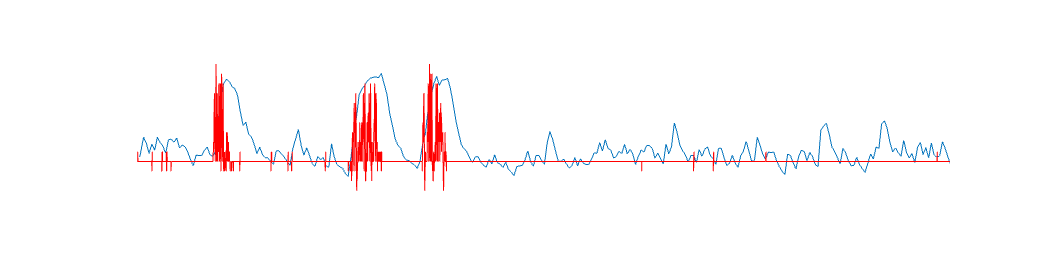

yyaxis left
plot(time,photoncount);
xlim([0 300])
ylim([530000 730000])
set(gca, 'XColor','none')
set(gca, 'YColor','none')
yyaxis right
plot(time_of_speed_seconds,speed, 'Color','r')
% ylabel('Speed cm/s','FontSize',24)
ylim([-10 35])
% yticks([-10 0 10 20])
xlim([0 300])
set(gca,'ytick',[0 20])
ylabel('Speed (cm/s)')
axis off
box off

% title('Intensity')